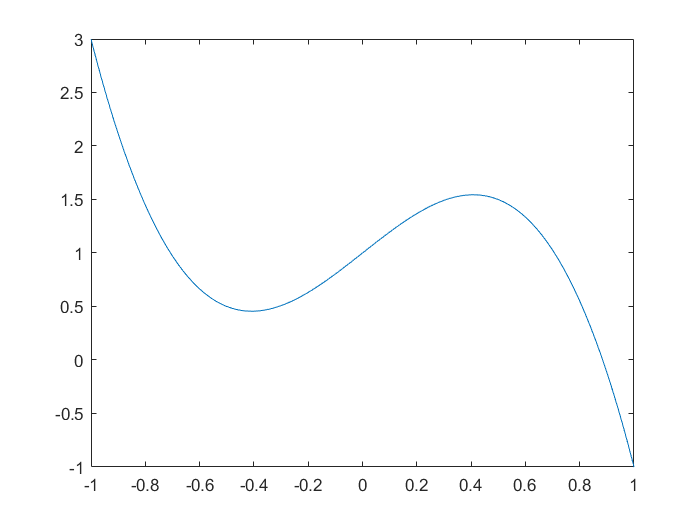

z=linspace(-1,1,101);
c=[-4 0 2 1];
p=polyval(c,z);
plot(z,p)

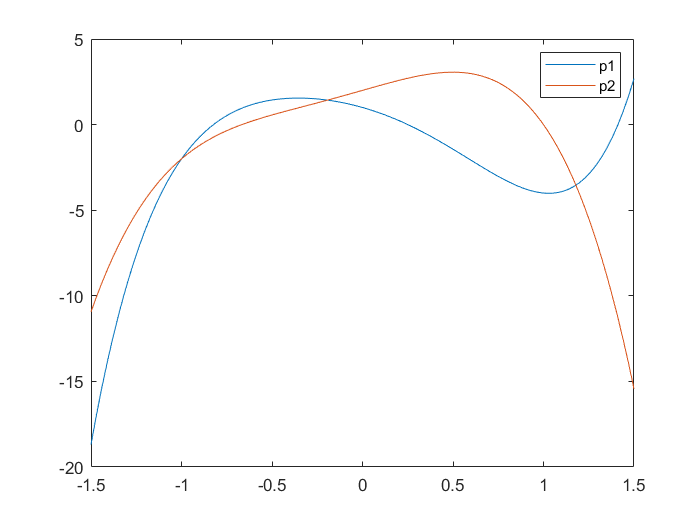

figure()

x=linspace(-3/2,3/2,101);
c1=[2 0 0 -4 -3 1];
p1=polyval(c1,x);
plot(x,p1)
hold on

c2=[-3 -2 0 3 2];
p2=polyval(c2,x);
plot(x,p2)
legend("p1","p2")


figure()
x=0.995:1.e-4:1.005;
c3=[1 -6 15 -20 15 -6 1];
p3=polyval(c3,x);
plot(x,p3)
hold on 

f=@(x) (x-1)^6

f = function_handle with value:
    @(x)(x-1)^6


fplot(f,[0.995 1.005])

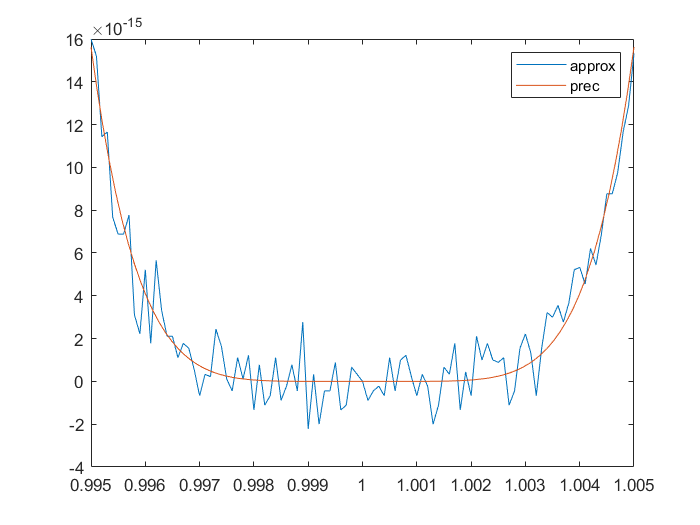

legend("approx","prec")


figure()
x=0:4;
y=[2 0 -1 -2 1];
plot(x,y,"or")
hold on
c=polyfit(x,y,4)

c =     0.2083   -1.4167    3.2917   -4.0833    2.0000


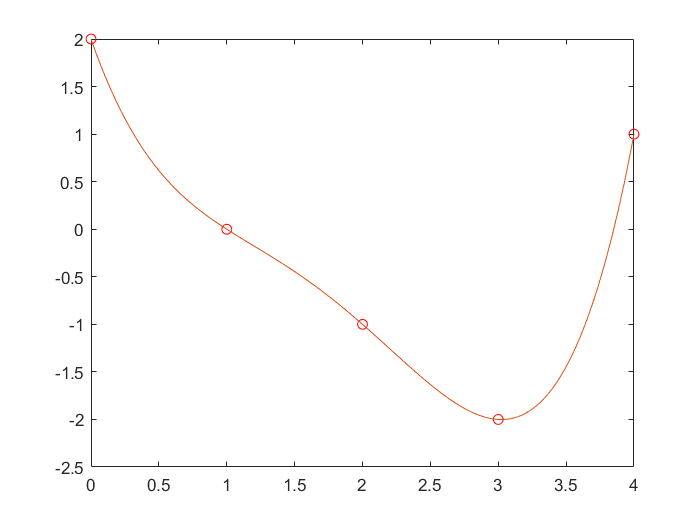

x=0:0.01:4;
y=polyval(c,x);
plot(x,y)


figure()
x=[-3 -1 2 3];
f=@(x) (1-x.^2).*atan(x)+exp(x)

f = function_handle with value:
    @(x)(1-x.^2).*atan(x)+exp(x)


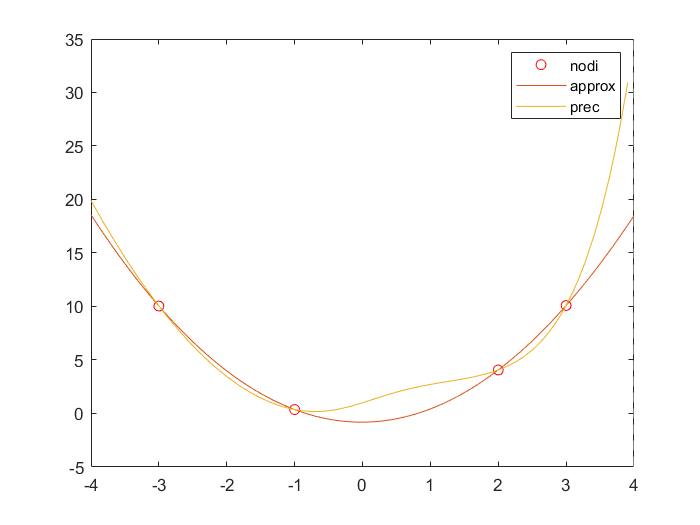

y=f(x);
plot(x,y,"or")
hold on
p=polyfit(x,y,3);
y=polyval(p,-4:0.1:4);
plot(-4:0.1:4,y)
fplot(f,[-4 4])
legend("nodi","approx","prec")


temp_media;
lat=-55:10:65;
figure()
hold on
plot(lat,T,"ob")
x=-55:30:65;
y=T(1:3:end);
plot(x,y,"*r")
p=polyfit(x,y,4);
y=polyval(p,-55:1:65);
plot(-55:1:65,y)
y=polyval(p,lat);
err=abs((y-T)./T*100)

err =     0.0000    0.5434    1.2653    0.0000    0.9233    0.1213    0.0000    0.4209    0.7971    0.0000    3.0365    4.3197    0.0000


p1=polyfit(lat,T,12);

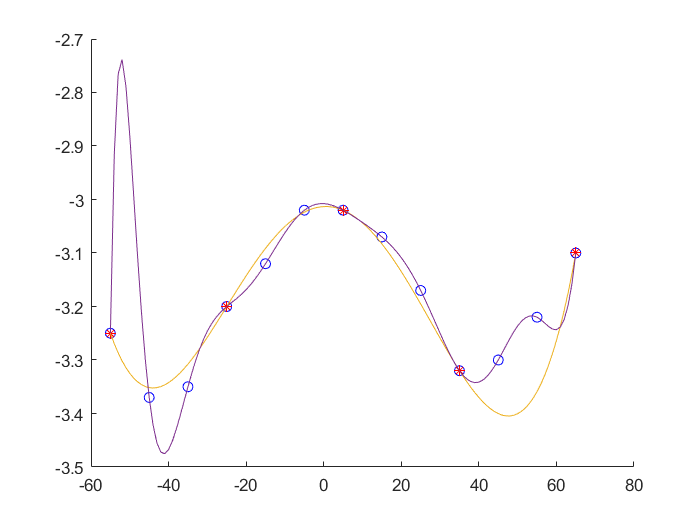

y=polyval(p1,-55:1:65);
plot(-55:1:65,y)

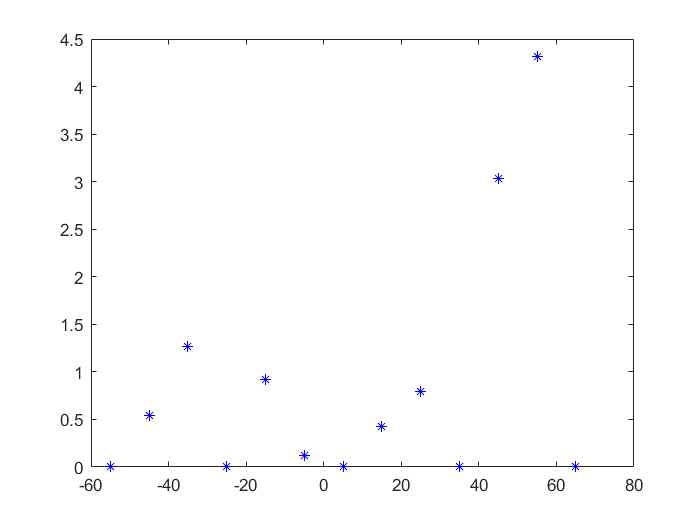


figure()
plot(lat,err,"*b")

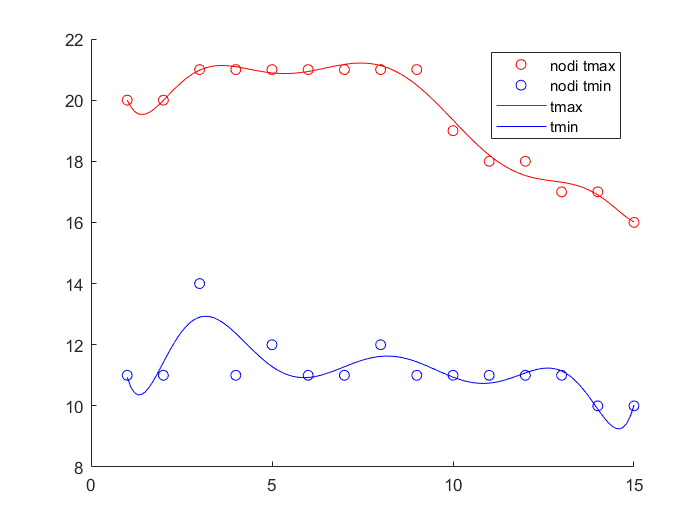


figure()
hold on
Tmax=[20 20 21 21 21 21 21 21 21 19 18 18 17 17 16];
Tmin=[11 11 14 11 12 11 11 12 11 11 11 11 11 10 10];
t=1:1:15;
pmax=polyfit(t,Tmax,8);
pmin=polyfit(t,Tmin,8);
x=1:0.1:15;
ymax=polyval(pmax,x);
ymin=polyval(pmin,x);
plot(t,Tmax,"or",t,Tmin,"ob",x,ymax,"r",x,ymin,"b")
legend("nodi tmax","nodi tmin","tmax","tmin")


figure()
hold on
f=@(x) exp(x);
N=100

N = 100

n=linspace(-1,1,N)

n =    -1.0000   -0.9798   -0.9596   -0.9394   -0.9192   -0.8990   -0.8788   -0.8586   -0.8384   -0.8182   -0.7980   -0.7778   -0.7576   -0.7374   -0.7172   -0.6970   -0.6768   -0.6566   -0.6364   -0.6162   -0.5960   -0.5758   -0.5556   -0.5354   -0.5152   -0.4949   -0.4747   -0.4545   -0.4343   -0.4141   -0.3939   -0.3737   -0.3535   -0.3333   -0.3131   -0.2929   -0.2727   -0.2525   -0.2323   -0.2121   -0.1919   -0.1717   -0.1515   -0.1313   -0.1111   -0.0909   -0.0707   -0.0505   -0.0303   -0.0101


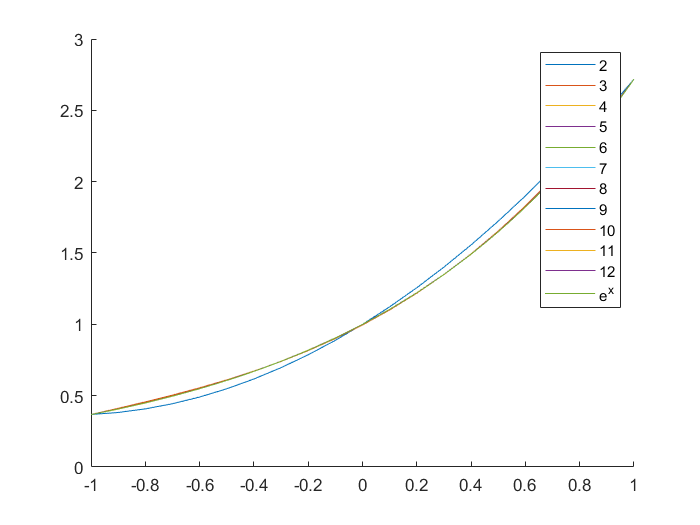

fn=f(n);
for i=2:1:12
    x=linspace(-1,1,i+1);
    y=f(x);
    p=polyfit(x,y,i);
    x1=-1:0.1:1;
    y=polyval(p,x1);
    plot(x1,y)
    for c=1:1:N
        e(c)=abs(fn(i)-polyval(p,n(i)));
    end
    err1(i-1)=max(e);
end
fplot(f,[-1 1])
legend("2","3","4","5","6","7","8","9","10","11","12","e^x")

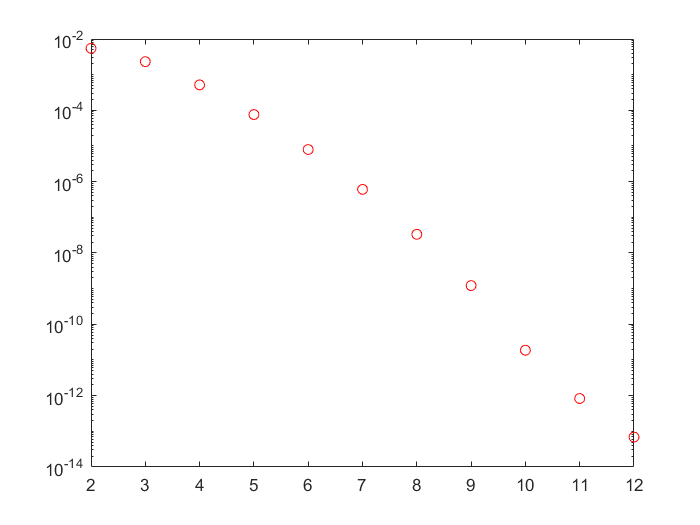

figure()
semilogy(2:12,err1,"or")